# **Rotational Inertial Matricies and Spacial Inertial Matricies**

**    For practice toward inverse and forward n link robot dynamics **

**Exercise 8.2 of Lynch**

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robotics 7752 | Ohio State University | 10/25/2022

with use of Modern Robotics by Kevin M. Lynch and Frank C. Park

**Objectives**

To find the 3D Inertial and Spacial Inertial matricies of the following dumbell. 

    **Methods**

    Using Steiners Theorem: Iq = Ib + m(q^T * q*I - q * q^T) where q is a 3 vector for position of the frame Ib

        equivelently, Iq = Ib + m*d^2

    Ib being the rotational inertial matrix for one geometric body. 

    The entire dumbell consisting of three bodies. the thin rod, and the two spheres

    The total rotational inertial matrix is the sum of the pieces. 

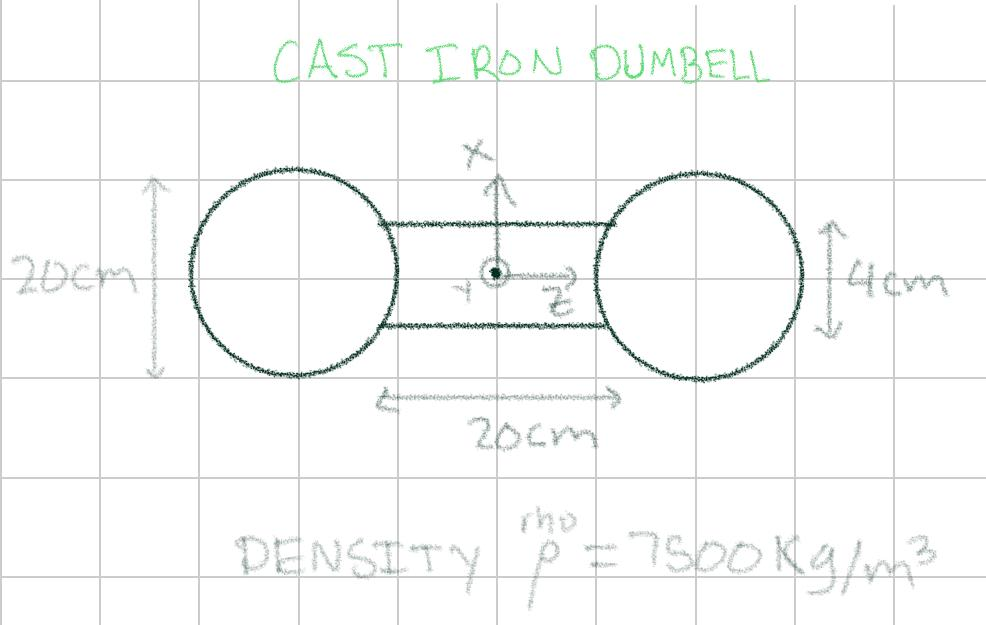

Dumbell Diagram

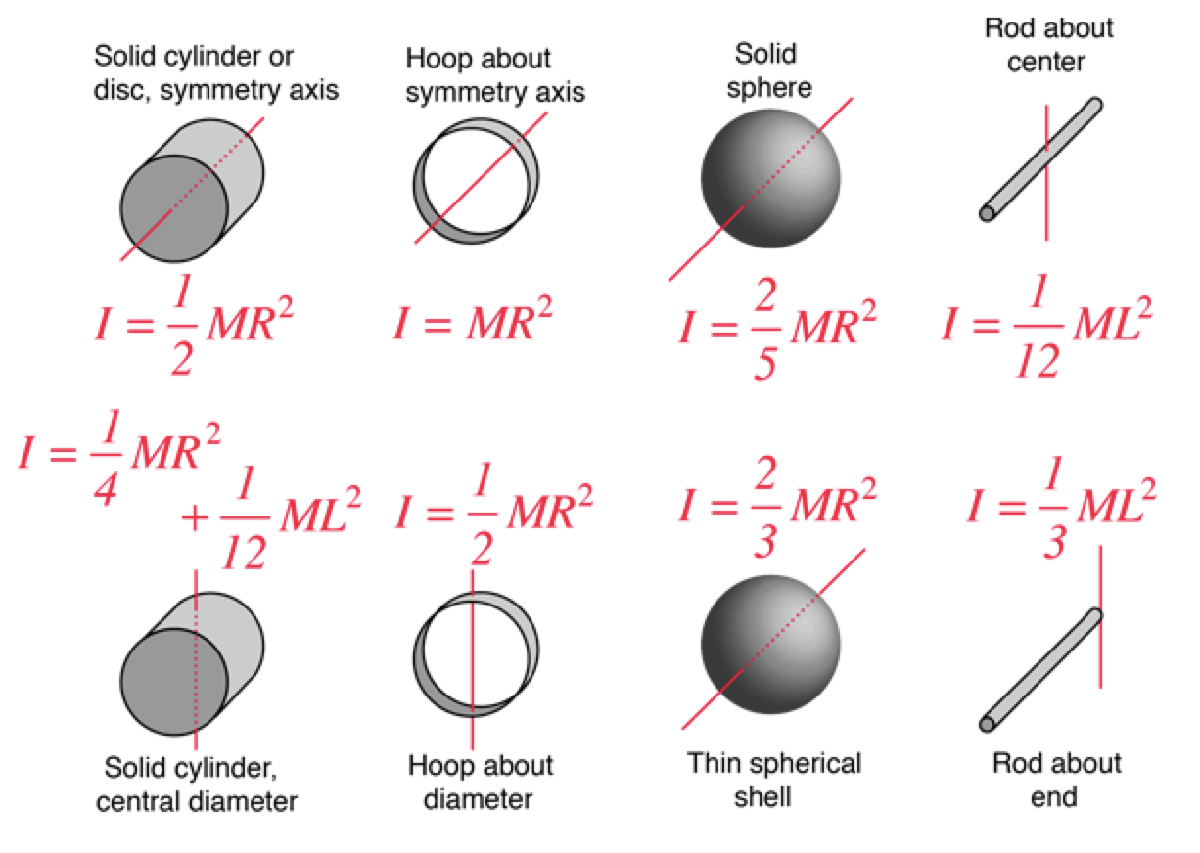

%Rotational Inertial Matricies
%Cylinder properties in its own frame
    %Cylinder C Struct - practice using structs here
c.r = 0.04; %m
c.l = 0.2; %m
c.rho = 7500; %kg/m^3
c.m = pi * c.r^2 * c.l * c.rho; %mass
c.xx = (1/12) * c.m * c.l^2; %rod about center formula 
c.yy = c.xx; %the same 
c.zz = 0.5 * c.m * c.r^2; %center of cylinder axis 
c.I_origin = [[c.xx 0 0];[0 c.yy 0];[0 0 c.zz]];

%Sphere Properties in its own frame (at its center) 
s.r = 0.1; %meters
s.rho = c.rho;
s.m = (4/3) * pi * s.r^3 * s.rho; %kg
s.xx = 2/5 * s.m * s.r^2; %formioli
s.yy = s.xx; s.zz = s.xx; %its a sphere
s.I_center = [[s.xx 0 0];[0 s.yy 0];[0 0 s.zz]];

%Parallel Axis theorem -> or 3d equivelent Steiners Theorem
s1.I_origin = steiners(s.I_center,[0 0 0.2],s.m);
s2.I_origin = steiners(s.I_center,[0 0 -0.2],s.m);

%Dumbell body frame (defined in figure) rotational inertial matrix
dumbell.Ib = c.I_origin + s1.I_origin + s2.I_origin;
disp('The Dumbells body frame rotational inertial matrix'), dumbell.Ib

The Dumbells body frame rotational inertial matrix


ans =    -2.2368   -2.5133   -2.5133
   -2.5133   -2.2368   -2.5133
   -2.5133   -2.5133    0.2574


%Spacial Inertial Matrix Gb = [[Ib 0];[0 m*I]]
dumbell.m = c.m + 2*s.m; %dumbell mass
dumbell.G = [[dumbell.Ib zeros(3,3)];[zeros(3,3) dumbell.m*eye(3)]];
disp('The Dumbells Spacial inertial matrix'), dumbell.G

The Dumbells Spacial inertial matrix


ans =    -2.2368   -2.5133   -2.5133         0         0         0
   -2.5133   -2.2368   -2.5133         0         0         0
   -2.5133   -2.5133    0.2574         0         0         0
         0         0         0   70.3717         0         0
         0         0         0         0   70.3717         0
         0         0         0         0         0   70.3717


function I_origin = steiners(I_body,q,mass)
    %q is a 3 vector from the space frame origin to the body frame origin
    %I_body is the 3by3 diagonal rotational inertia matrix made of Ixx Iyy
        %Izz about the objects own center of mass frame
    I_origin = I_body + mass * (q'*q*eye(3) - q*q');
end 